load('loadcell.mat');
rawData = out.simout1

rawData = 1.0e+04 *

         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0


Nround = 21;
Nsample = 201;

% Manipulate matrix
MassData = rawData(:, 2)

MassData =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


analogs = rawData(:, 1)

analogs =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


anaData = reshape(analogs, [Nsample, Nround])'

anaData =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0008         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0008         0         0         0         0
    0.1040    0.1023    0.1080    0.1072    0.1096    0.1040    0.1040    0.1088    0.0999    0.1048    0.1048    0.1080    0.1088    0.1064    0.1072    0.1048    0.1096    0.1072    0.1056    0.1064    0.1064    0.1072    0.1080    0.1056    0.1088    0.1064    0.1056    0.1048    0.1015    0.1023    0.1080    0.1023    0.1072    0.1015    0.1088    0.1080    0.1072    0.1096    0.1064    0.1048    0.1112    0.1056    0.1032    0.1088    0.1040    0.1056    0.1015    0.1048    0.104


% to be used
anaData = cast(anaData, "double");
voltData = anaData %.* 3.3 ./ 4096.0

voltData =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0008         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0008         0         0         0         0
    0.1040    0.1023    0.1080    0.1072    0.1096    0.1040    0.1040    0.1088    0.0999    0.1048    0.1048    0.1080    0.1088    0.1064    0.1072    0.1048    0.1096    0.1072    0.1056    0.1064    0.1064    0.1072    0.1080    0.1056    0.1088    0.1064    0.1056    0.1048    0.1015    0.1023    0.1080    0.1023    0.1072    0.1015    0.1088    0.1080    0.1072    0.1096    0.1064    0.1048    0.1112    0.1056    0.1032    0.1088    0.1040    0.1056    0.1015    0.1048    0.10


meanVoltData = mean(voltData, 2)

meanVoltData =     0.0000
    0.1065
    0.2257
    0.3460
    0.4685
    0.5917
    0.7163
    0.8430
    0.9683
    1.0950


stdVolt = std(voltData, 0, 2)

stdVolt =     0.0002
    0.0026
    0.0029
    0.0033
    0.0031
    0.0030
    0.0035
    0.0038
    0.0031
    0.0029



Mass = 0 : 0.5 : 10 % kg

Mass =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000



g = 9.81

g = 9.8100

Force = Mass * g

Force =          0    4.9050    9.8100   14.7150   19.6200   24.5250   29.4300   34.3350   39.2400   44.1450   49.0500   53.9550   58.8600   63.7650   68.6700   73.5750   78.4800   83.3850   88.2900   93.1950   98.1000


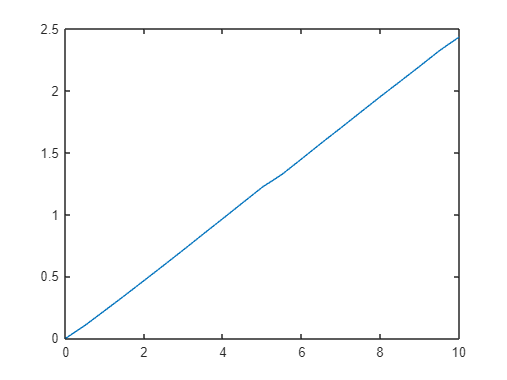

plot(Mass, meanVoltData)

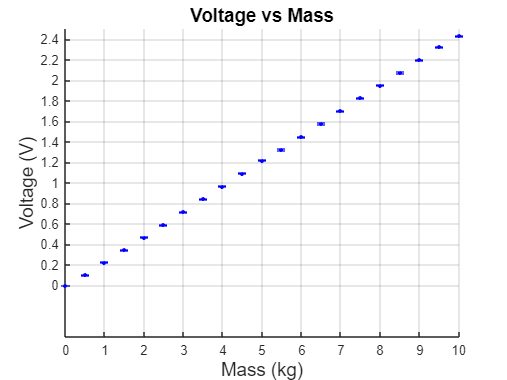


figure;
hold on;
graph_V = errorbar(Mass, meanVoltData, 2*stdVolt, ...
    'or', 'LineWidth', 1.0, 'MarkerSize', 2, 'Color', 'b', 'MarkerEdgeColor', 'b', 'MarkerFaceColor', 'b');
% ตกแต่ง
xticks(0:1:10);
xticklabels(0:1:10);
yticks(0:0.2:3.4);
yticklabels(0:0.2:3.4);
grid on;
title('Voltage vs Mass', 'FontSize', 14);
xlabel('Mass (kg)', 'FontSize', 14); 
ylabel('Voltage (V)', 'FontSize', 14); 
%%legend('Non-Shield South','Location', 'southeast');

hold off;

x = Mass;
y = meanVoltData;

% Get coefficients of a line fit through the data.
coefficients = polyfit(x, y, 1)

coefficients =     0.2456   -0.0166


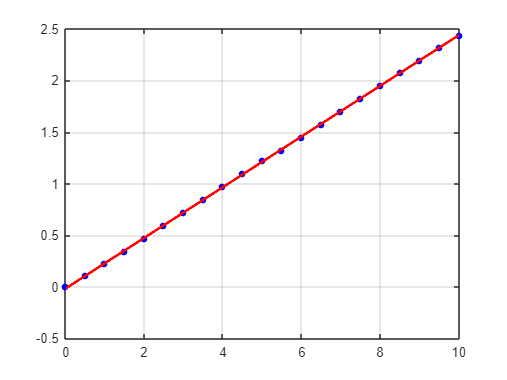

% Create a new x axis with exactly 1000 points (or whatever you want).
xFit = linspace(min(x), max(x), 1000);
% Get the estimated yFit value for each of those 1000 new x locations.
yFit = polyval(coefficients , xFit);
% Plot everything.
plot(x, y, 'b.', 'MarkerSize', 15); % Plot training data.
hold on; % Set hold on so the next plot does not blow away the one we just drew.
plot(xFit, yFit, 'r-', 'LineWidth', 2); % Plot fitted line.
grid on;

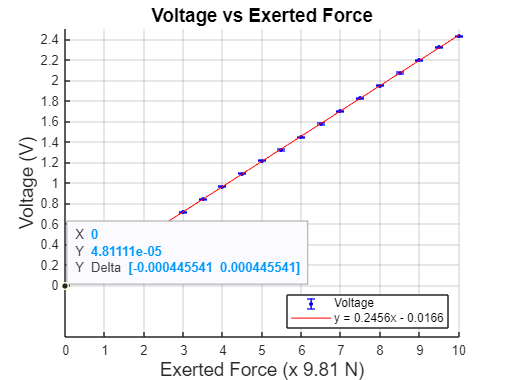

% plot and fitting
figure;
hold on;
graph_V = errorbar(Mass, meanVoltData, 2*stdVolt, ...
    'or', 'LineWidth', 1.0, 'MarkerSize', 2, 'Color', 'b', 'MarkerEdgeColor', 'b', 'MarkerFaceColor', 'b');
plot(xFit, yFit, 'r-', 'LineWidth', 0.8); % Plot fitted line.

% ตกแต่ง
xticks(0:1:10);
xticklabels(0:1:10);
yticks(0:0.2:3.4);
yticklabels(0:0.2:3.4);
grid on;
title('Voltage vs Exerted Force', 'FontSize', 14);
xlabel('Exerted Force (x 9.81 N)', 'FontSize', 14); 
ylabel('Voltage (V)', 'FontSize', 14); 
legend('Voltage', 'y = 0.2456x - 0.0166','Location', 'southeast');
datatip(graph_V);

hold off;